## Modélisation de l'activité électrique du cerveau 

La température de surface de la planète dépend largement des émissions de C02 et leurs évolutions dans le temps. L'analyse de la température de surface GISS ver. 4 (GISTEMP v4) est une estimation du changement global de la température de surface.Le fichier "climat_CO2.txt contient 3 variables : 

**year**	: années de 1959 à 2020 

**CO2**	: CO2 exprimé en fraction molaire dans l'air sec, micromol/mol, abrégé en ppm. Il est mesuré sur le Mauna Loa (sommet de l'archipel d'Hawai) depuis la fin des années 50.

**gistemp** : anomalies de température en dégrés Celsius. Il s'agit des écarts entre la température annuelle et la température moyenne de la période 1951-1980.

On s'intéresse ici à la modélisation du niveau de CO2 dans l'atmosphère en fonction du temps

#### Import des données et visualisation

On charge les données.

clear all
T = readtable('/home/adele/ECL-projects/Matlab/Stat/climat_CO2.txt','delimiter', '\t','ReadVariableNames',true);
summary(T)


T: 62×3 table

Variables:

    year: double
    CO2: double
    gistemp: double

Statistics for applicable variables:

               NumMissing        Min             Median            Max              Mean             Std    

    year           0               1959        1.9895e+03            2020        1.9895e+03        18.0416  
    CO2            0           315.9800          353.8250        414.2400          356.3858        29.1110  
    gistemp        0            -0.1960            0.3245          0.9967            0.3398         0.3082  



La colonne qui nous intéresse est CO2 qu'on voudrait modéliser en fonction de year. 

#### Q1/ Représenter les données.

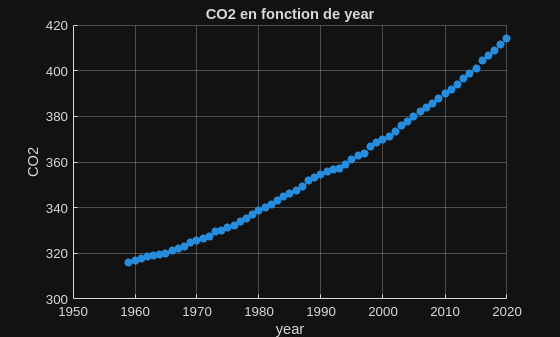

CO2 = T.CO2;
Y = T.year;

scatter(Y, CO2, 'filled');
xlabel('year');
ylabel('CO2');
title('CO2 en fonction de year');
grid on;

#### Q2/ Mettre en place un modèle de régression permettant d'expliquer l'évolution du CO2 en fonction des années.

model = 'CO2 ~ year';
mdl_CO2 = fitlm(T,model)

mdl_CO2 = Linear regression model:
    CO2 ~ 1 + year

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -2826.3     54.116    -52.226    1.0079e-51
    year            1.5997     0.0272     58.814    9.2533e-55


Number of observations: 62, Error degrees of freedom: 60
Root Mean Squared Error: 3.83
R-squared: 0.983,  Adjusted R-Squared: 0.983
F-statistic vs. constant model: 3.46e+03, p-value = 9.25e-55

#### **Q3/**  Donner les v**aleurs des paramètres du modèle.**

b0 = mdl_CO2.Coefficients.Estimate(1);
b1 = mdl_CO2.Coefficients.Estimate(2); 

fprintf('Modèle : CO2 = β₀ + β₁ × year + ε\n');

Modèle : CO2 = β₀ + β₁ × year + ε


fprintf('β̂₀ = %.4f\n', b0);

β̂₀ = -2826.2821


fprintf('β̂₁ = %.4f\n', b1);

β̂₁ = 1.5997


fprintf('Équation : Ŷ = %.4f + (%.4f) × Latitude\n', b0, b1);

Équation : Ŷ = -2826.2821 + (1.5997) × Latitude


#### **Q3bis/**  Peut-on dire que le niveau de CO2 augmente en fonction du temps ? 

b1 > 0 donc le niveau de CO2 augmente avec le temps

#### **Q4/**  Sur un même graphique, tracer la droite de régression et les observations.

On peut alors tracer le résultat de la régression linéaire

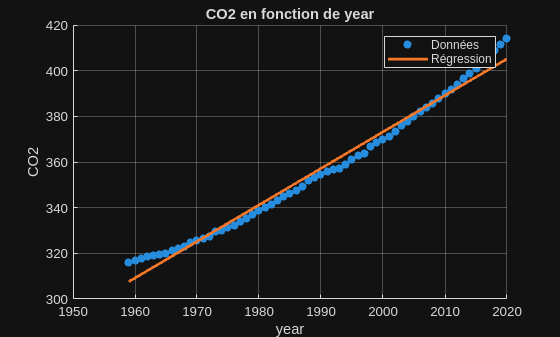

scatter(Y, CO2, 'filled');
hold on;
xlabel('year');
ylabel('CO2');
title('CO2 en fonction de year');
grid on;

year_range = linspace(min(Y), max(Y), 100);

CO2_pred_line = b0 + b1 * year_range;
plot(year_range, CO2_pred_line,'LineWidth',2);
hold off;
legend('Données', 'Régression');

#### **Q5/ Quelle est la part de variance expliquée par le modèle ?**

R2 = mdl_CO2.SSR/mdl_CO2.SST;

fprintf('R² = %.4f (%.2f%%)\n', R2, R2*100);

R² = 0.9830 (98.30%)


#### Prédiction :

#### **Q6/**  D'après ce modèle, quel sera le niveau de CO2 moyen sur la période 2020-2050 ? Est-il possible qu'une mesure du CO2 dépasse 500ppm sur la période ? 

On répondra à ces questions par un graphique où toutes les sources d'incertitudes seront représentées. 

annees = linspace(2020, 2050, 100)';

x0 = table(annees, 'VariableNames', {'year'});
[y_pred,IC] = predict(mdl_CO2,x0,'Prediction','Observation');
m = mean(y_pred)

m = 429.1736

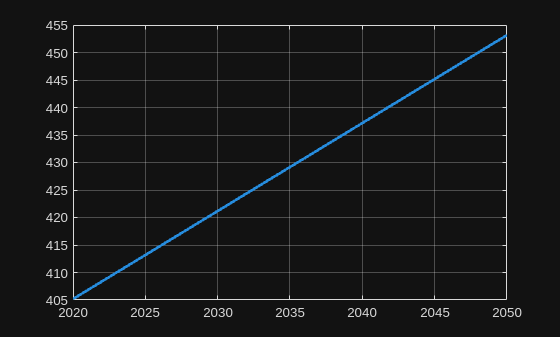

plot(annees, y_pred,'LineWidth',2);
grid on;
hold on;

L'Intervalle de confiance de la valeur de CO2 pour l'année 2050 est [444.77,461.67] donc la probabilité que une valeur de CO2 dépasse 500ppm est très faible

#### **Q7/ Que pensez-vous du modèle précédent ? **

#### **Q8/ Proposer un modèle plus adapté. Interpréter.**

gistemp = T.gistemp; 
model2 = 'CO2 ~ year + gistemp'; % On rajoute un paramètre dans le modèle
mdl_CO22 = fitlm(T,model2)

mdl_CO22 = Linear regression model:
    CO2 ~ 1 + year + gistemp

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -2325.6       149.51    -15.555    1.5299e-22
    year            1.3454     0.075865     17.734    2.5617e-25
    gistemp         15.763        4.441     3.5493    0.00076542


Number of observations: 62, Error degrees of freedom: 59
Root Mean Squared Error: 3.51
R-squared: 0.986,  Adjusted R-Squared: 0.985
F-statistic vs. constant model: 2.07e+03, p-value = 2.27e-55

R2 = mdl_CO22.SSR/mdl_CO22.SST;

fprintf('R² = %.4f (%.2f%%)\n', R2, R2*100);

R² = 0.9860 (98.60%)


n = length(CO2);
c = tinv(0.975, n-3)

c = 2.0010

t_stat de gistemp est plus grande que c donc l'ajout de ce paramètre a un effet significatif

#### **Q9 / Pour ce nouveau modèle est-il possible qu'une mesure du CO2 dépasse 500ppm sur la période ?**

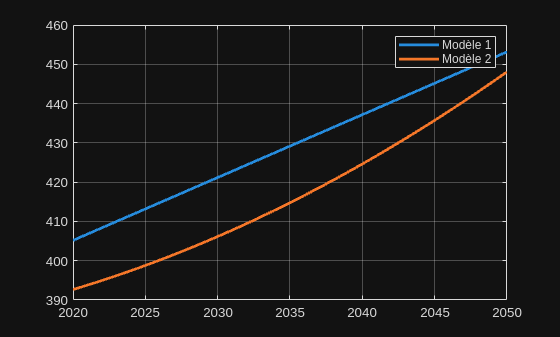

annees = linspace(2020, 2050, 100);
gistemp_2 = linspace(min(gistemp),max(gistemp),100);
CO2_pred2 = mdl_CO22.Coefficients.Estimate(1) + mdl_CO22.Coefficients.Estimate(2) * annees + mdl_CO22.Coefficients.Estimate(3)*(gistemp_2).^2;
plot(annees, CO2_pred2,'LineWidth',2);
grid on
legend('Modèle 1','Modèle 2')

annees = linspace(2020, 2050, 100)';

x0 = table(annees, 'VariableNames', {'year'});
[y_pred,IC] = predict(mdl_CO2,x0,'Prediction','Observation');